%%INPUTS
run AircraftData.mlx;

Vanguard = struct with fields:
              MTOW: 142740
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


Vanguard = struct with fields:
              MTOW: 142740
       WingLoading: 93.5500
              Wing: [1×1 struct]
          Fuselage: [1×1 struct]
      VerticalTail: [1×1 struct]
    HorizontalTail: [1×1 struct]


%Flight Conditions
h = 0 %ft

h = 0

V = 100; %kts
[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
AirDens = DensRat*2.3769*10^-3

AirDens = 0.0024

V=V*1.688

V = 168.8000

AoA = 0;

for i = 1:1:31
    %Wing Parameters
    QuarterSweep = Vanguard.Wing.QuarterChordSweep %deg
    Df = Vanguard.Fuselage.Diameter;
    TaperRatio = Vanguard.Wing.TaperRatio;
    S = Vanguard.Wing.S;
    b = Vanguard.Wing.b;
    AR = Vanguard.Wing.AR;
    SweepLE = atand(tand(QuarterSweep)-4/AR*((0-0.25)*(1-TaperRatio)/(1+TaperRatio)))
    InstallAngle = 2.63
    LiftCurveSlope = 0.0846 %Per deg
    Yehudi(i) = i-1;
    Cr(i) = Vanguard.Wing.S/(2*Yehudi(i)+(1+Vanguard.Wing.TaperRatio)/2*(Vanguard.Wing.b-2*Yehudi(i)))
    
    %For clean wing
    daCLmax = 1.2
    MaxLiftCoefRatio = 0.9
    
    %Airfoil Parameters
    ZeroLiftAngle = Vanguard.Wing.Airfoil.ZeroLiftAngle;
    ClMax = Vanguard.Wing.Airfoil.Clmax;
    AirfoilStallAngle = Vanguard.Wing.Airfoil.StallAngle;
    Cla = Vanguard.Wing.Airfoil.Cla;
    
    
    %Clean wing
    CLMax = MaxLiftCoefRatio*ClMax
    WingStallAngle = CLMax/LiftCurveSlope+ZeroLiftAngle+daCLmax
    
    %Flapped From Graphs
    FlapDeflec = 40 %Deg
    ddZeroLiftAngle = -0.45 %For Slotted flaps with cf/c = 0.3 at 40deg deflection
    dZeroLiftAngle = ddZeroLiftAngle*FlapDeflec
    
    %%CALCULATIONS
    
    %Flapped Wing
    y1flap=Df/2
    y2flap=0.75*b/2
    y3flap=0
    y4flap=0
    
    y3Aileron = 56.05
    
    c1flap = YehudiChord(y1flap,Yehudi(i),Cr(i),TaperRatio,b)
    c2flap = YehudiChord(y2flap,Yehudi(i),Cr(i),TaperRatio,b)
    c3flap = YehudiChord(y3flap,Yehudi(i),Cr(i),TaperRatio,b)
    c4flap = YehudiChord(y4flap,Yehudi(i),Cr(i),TaperRatio,b)
    
    if y1flap>=Yehudi(i)
        SWF(i) = 2*((c1flap+c2flap)/2*(y2flap-y1flap) + (c3flap+c4flap)/2*(y4flap-y3flap));
    else
        SWF(i) = 2*(c1flap*(Yehudi(i)-y1flap)+(c1flap+c2flap)/2*(y2flap-Yehudi(i)) + (c3flap+c4flap)/2*(y4flap-y3flap));
    end
    
    SweepFactor = (1-0.08*(cosd(QuarterSweep))^2)*(cosd(QuarterSweep))^(3/4);
    
    dAirfoilStallAngle = -4*10^(-7)*FlapDeflec^4+3*10^(-5)*FlapDeflec^3-0.0019*FlapDeflec^2-0.024*FlapDeflec;
    
    AirfoilStallAngleFlapped = AirfoilStallAngle + dAirfoilStallAngle;
    
    ZeroLiftAngleFlapped = ZeroLiftAngle + dZeroLiftAngle;
    
    ClMaxFlapped = Cla*(AirfoilStallAngleFlapped - ZeroLiftAngleFlapped-daCLmax);
    
    dClMaxFlapped = ClMaxFlapped - ClMax;
    dCLMaxFlapped = dClMaxFlapped*SWF(i)*SweepFactor/S;
    
    CLMaxFlapped(i) = CLMax + dCLMaxFlapped;
end

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr = 18.4723

daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 17.0165

c2flap = 10.1598

c3flap = 18.4723

c4flap = 18.4723

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 17.0585

c2flap = 10.1339

c3flap = 18.3391

c4flap = 18.3391

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 17.1058

c2flap = 10.1101

c3flap = 18.2078

c4flap = 18.2078

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 17.1583

c2flap = 10.0884

c3flap = 18.0784

c4flap = 18.0784

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 17.2164

c2flap = 10.0687

c3flap = 17.9508

c4flap = 17.9508

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 17.2803

c2flap = 10.0513

c3flap = 17.8249

c4flap = 17.8249

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 17.3502

c2flap = 10.0361

c3flap = 17.7009

c4flap = 17.7009

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 17.4264

c2flap = 10.0231

c3flap = 17.5785

c4flap = 17.5785

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 17.4578

c2flap = 10.0126

c3flap = 17.4578

c4flap = 17.4578

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 17.3388

c2flap = 10.0045

c3flap = 17.3388

c4flap = 17.3388

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 17.2214

c2flap = 9.9989

c3flap = 17.2214

c4flap = 17.2214

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 17.1056

c2flap = 9.9961

c3flap = 17.1056

c4flap = 17.1056

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 16.9913

c2flap = 9.9959

c3flap = 16.9913

c4flap = 16.9913

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 16.8785

c2flap = 9.9987

c3flap = 16.8785

c4flap = 16.8785

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785   16.7672


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 16.7672

c2flap = 10.0044

c3flap = 16.7672

c4flap = 16.7672

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785   16.7672   16.6574


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 16.6574

c2flap = 10.0134

c3flap = 16.6574

c4flap = 16.6574

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785   16.7672   16.6574   16.5490


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 16.5490

c2flap = 10.0256

c3flap = 16.5490

c4flap = 16.5490

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785   16.7672   16.6574   16.5490   16.4420


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 16.4420

c2flap = 10.0413

c3flap = 16.4420

c4flap = 16.4420

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785   16.7672   16.6574   16.5490   16.4420   16.3363


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 16.3363

c2flap = 10.0608

c3flap = 16.3363

c4flap = 16.3363

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785   16.7672   16.6574   16.5490   16.4420   16.3363   16.2321


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 16.2321

c2flap = 10.0842

c3flap = 16.2321

c4flap = 16.2321

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785   16.7672   16.6574   16.5490   16.4420   16.3363   16.2321   16.1291


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 16.1291

c2flap = 10.1117

c3flap = 16.1291

c4flap = 16.1291

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785   16.7672   16.6574   16.5490   16.4420   16.3363   16.2321   16.1291   16.0275


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 16.0275

c2flap = 10.1437

c3flap = 16.0275

c4flap = 16.0275

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785   16.7672   16.6574   16.5490   16.4420   16.3363   16.2321   16.1291   16.0275   15.9271


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 15.9271

c2flap = 10.1804

c3flap = 15.9271

c4flap = 15.9271

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785   16.7672   16.6574   16.5490   16.4420   16.3363   16.2321   16.1291   16.0275   15.9271   15.8280


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 15.8280

c2flap = 10.2222

c3flap = 15.8280

c4flap = 15.8280

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785   16.7672   16.6574   16.5490   16.4420   16.3363   16.2321   16.1291   16.0275   15.9271   15.8280   15.7301


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 15.7301

c2flap = 10.2695

c3flap = 15.7301

c4flap = 15.7301

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785   16.7672   16.6574   16.5490   16.4420   16.3363   16.2321   16.1291   16.0275   15.9271   15.8280   15.7301   15.6334


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 15.6334

c2flap = 10.3226

c3flap = 15.6334

c4flap = 15.6334

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785   16.7672   16.6574   16.5490   16.4420   16.3363   16.2321   16.1291   16.0275   15.9271   15.8280   15.7301   15.6334   15.5378


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 15.5378

c2flap = 10.3821

c3flap = 15.5378

c4flap = 15.5378

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785   16.7672   16.6574   16.5490   16.4420   16.3363   16.2321   16.1291   16.0275   15.9271   15.8280   15.7301   15.6334   15.5378   15.4435


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 15.4435

c2flap = 10.4485

c3flap = 15.4435

c4flap = 15.4435

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785   16.7672   16.6574   16.5490   16.4420   16.3363   16.2321   16.1291   16.0275   15.9271   15.8280   15.7301   15.6334   15.5378   15.4435   15.3503


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 15.3503

c2flap = 10.5224

c3flap = 15.3503

c4flap = 15.3503

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785   16.7672   16.6574   16.5490   16.4420   16.3363   16.2321   16.1291   16.0275   15.9271   15.8280   15.7301   15.6334   15.5378   15.4435   15.3503   15.2582


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 15.2582

c2flap = 10.6044

c3flap = 15.2582

c4flap = 15.2582

QuarterSweep = 0

SweepLE = 2.6888

InstallAngle = 2.6300

LiftCurveSlope = 0.0846

Cr =    18.4723   18.3391   18.2078   18.0784   17.9508   17.8249   17.7009   17.5785   17.4578   17.3388   17.2214   17.1056   16.9913   16.8785   16.7672   16.6574   16.5490   16.4420   16.3363   16.2321   16.1291   16.0275   15.9271   15.8280   15.7301   15.6334   15.5378   15.4435   15.3503   15.2582   15.1671


daCLmax = 1.2000

MaxLiftCoefRatio = 0.9000

CLMax = 1.4400

WingStallAngle = 15.2213

FlapDeflec = 40

ddZeroLiftAngle = -0.4500

dZeroLiftAngle = -18

y1flap = 7.7500

y2flap = 44.2500

y3flap = 0

y4flap = 0

y3Aileron = 56.0500

c1flap = 15.1671

c2flap = 10.6955

c3flap = 15.1671

c4flap = 15.1671

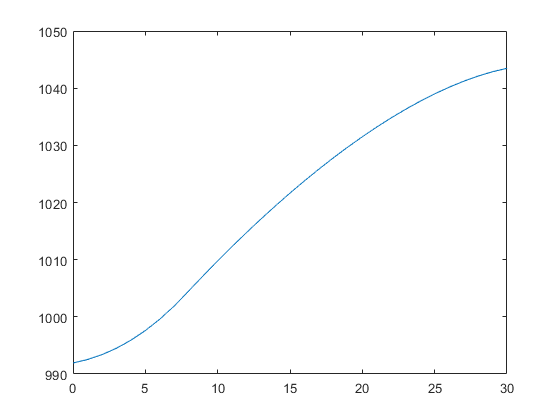


plot (Yehudi, SWF)

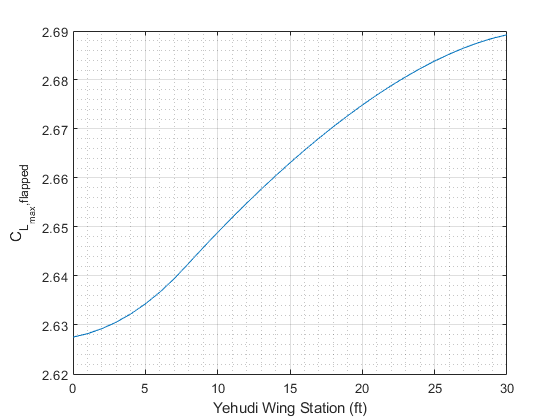


plot (Yehudi, CLMaxFlapped)

grid on 
grid minor

xlabel ('Yehudi Wing Station (ft)')
ylabel ('C_{L_{max},flapped}')